# Lorenz Multiple Parameter Identification

The Lorenz system considered in this example is defined as,


$$\dot{x}_1(t)=\theta_1(x_2(t)-x_1(t)),$$



$$\dot{x}_2(t)=x_1(t)(\theta_2-x_3(t))-x_2(t),$$



$$\dot{x}_3(t)=x_1(t)x_2(t)-\theta_3x_3(t),$$



$$y(t)=x_1(t),$$


where the states $x(t)\in\mathbb{R}^3$ and the parameters $\theta\in\mathbb{R}^3$. In this example the underlying true system is initialized at initial states $x^{\star}(0)=[-2.5;-0.5;20]$ and parameters $\theta^{\star}=[10;28;8/3]$ characterizing the true system as chaotic. The goal of this example is to use Spline-MHE algorithm to use the true model output $y(t)=x_1(t)$ corrupted with Gaussian noise to estimate the model initial states $x^\ast(0)$ and identify the model parameters $\theta^\ast$.

#### Generate Noisy Data

The following code generates and plots the output trajectory from the true model and corrupts it with Gaussian noise:

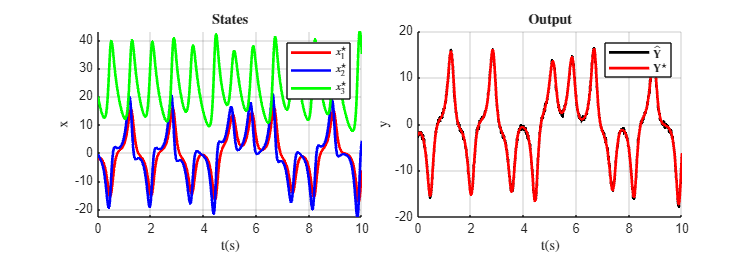

clear
global iteration_data Sol;
addpath("Support_Functions\");

T = 10; % simulation time
N = 1000; % number of time step intervals
dt = T/N; % time step size

n_x = 3;
n_y = 1;
n_theta = 3;

% True Initial condition and parameter values
x0_star = [-2.5;-0.5;20];
theta_star = [10;28;8/3];

true_param = {x0_star,theta_star};

% Simulate true model
[x_star,y_star,Y_hat] = Lorenz_sim(true_param,N,dt,10,true); % SNR=10

#### Initialize Spline-MHE

For initializing the Spline-MHE algorithm, the initial guess of $x(0)$ and $\theta$, the smoothing spline estimate of noisy data $\mathbf{\hat{Y}}^{est}$, along with the hyperparameter choices are required. Here the initial $x(0)$ and $\theta$ are arbitrarily chosen by linearly scaling $x^\star(0)$ and $\theta^\star$ using scaling factors $r_x
$ and $r_\theta$. The Spline-MHE hyperparameter can then be selected based on the heuristics presented in the paper. For demonstration purposes, the hyperparameter choices for number of moving horizons $n_h=1$, number of multiple shooting spline segments over a horizon $n_s=20$, spline order $n_p=3$, number of knots per spline segment $n_\tau=8$, the set of intermediate constraint points $\mathcal{K}$, and a weighting matrix $\mathbf{W=I}$ are chosen for this example. The smoothing spline estimate $\mathbf{\hat{Y}}^{est}=\big(\Phi\Phi^\dagger_{\lambda,\delta}\mathbf{\hat{Y}}^\top\big)^\top$ of the noisy data for $\Phi^\dagger_{\lambda,\delta}=\big(\Phi^\top\Phi+\lambda\Phi^{(\delta)\top}\Phi^{(\delta)}\big)^{-1}\Phi^\top$ is obtained by first finding a minimizing value of the smoothness factor $\lambda$ for a chosen spline derivative order $\delta$ using a Generalized Cross-Validation (GCV) scheme. The following code initializes the Spline-MHE algorithm:

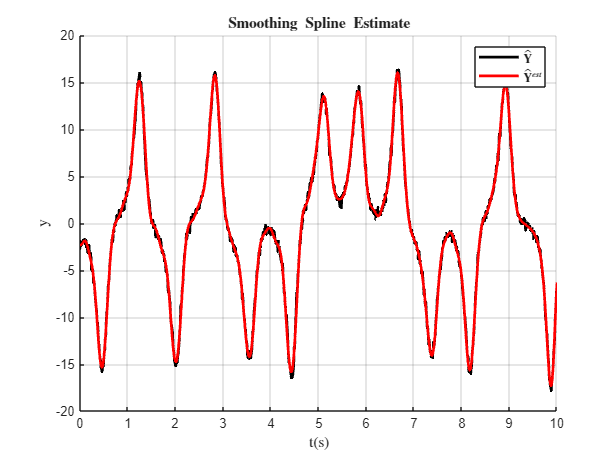

% Initial state and parameter Scaling factors 
r_x = 2;
r_theta = 2;

x0_init = x0_star*r_x; % x(0) initial guess
theta_init = theta_star*r_theta; % theta initial guess


% Spline-MHE hyperparameter selection
nh = 1; % number of moving horizons
ns = 20; % number of multiple-shooting spline segments per horizon

np = 3; % spline order
n_tau = 8; % number of spline knots

%(Note: ns*nh must be a multiple of N)
Ns = N/(ns*nh); % number of discrete points within a spline segment

Kappa = ceil(linspace(1,Ns,(np+(n_tau-2)))); % Intermediate constraint point set


% Smoothing spline estimate using GCV for lambda
delta = 2; % spline derivative order
[lambda,Y_hat_est] = GCV(Y_hat,delta,np*2,n_tau*10,N,dt,true);

#### Solve Spline-MHE

The initial guess of $x(0)$ and $\theta$, the smoothing spline estimate $\mathbf{\hat{Y}}^{est}$, and the Spline-MHE hyperparameter choices can now be used to solve the Spline-MHE NLP to estimate the model initial states $x^\ast(0)$ and identify the model parameters $\theta^\ast$. The following code solves the Spline-MHE NLP:

Sol = SplineMHE_Lorenz(x0_init,theta_init,Y_hat_est,delta,Kappa,N,dt,ns,nh,np,n_tau)

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
callback_fun  |  52.00ms (  1.63ms)  50.54ms (  1.58ms)        32
       nlp_f  |  22.00ms (578.95us)  16.67ms (438.58us)        38
       nlp_g  |   6.00ms (157.89us)   7.86ms (206.97us)        38
  nlp_grad_f  |  14.00ms (424.24us)  23.34ms (707.36us)        33
  nlp_hess_l  | 259.00ms (  8.35ms) 260.58ms (  8.41ms)        31
   nlp_jac_g  | 101.00ms (  3.06ms)  98.70ms (  2.99ms)        33
       total  | 685.00ms (685.00ms) 685.06ms (685.06ms)         1


Sol = 6×1 table
                                  Horizon-1  
                                 ____________

    x*(0)                        {3×1 double}
    θ*                           {3×1 double}
    Convergence Cost             {[  0.0430]}
    Solver Iterations            {[      31]}
    NLP Construction Time (s)    {[  0.3290]}
    NLP Solve Time (s)           {[  0.6851]}


The following code animates the solver iterations:

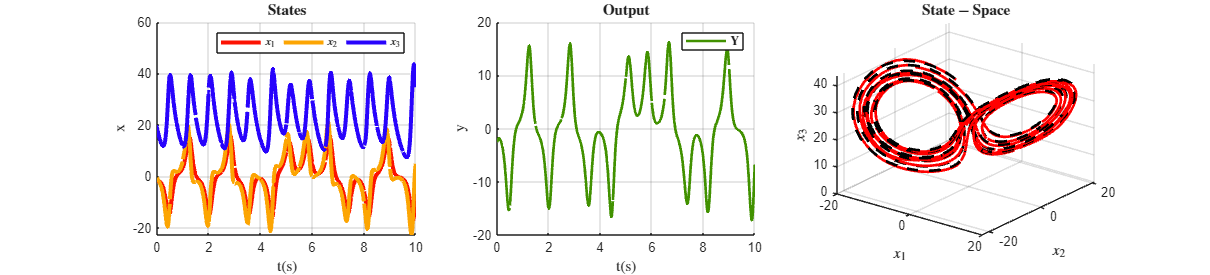

animate_Lorenz(iteration_data,x_star,y_star,Y_hat,N,dt,nh,ns,n_x,n_y);